% Caleb Distel | SES 598
% 10/29/2025
% Data Rate Conversion matlab activity

## Clear Workspace

close all; clear; clc;

## Downsampling

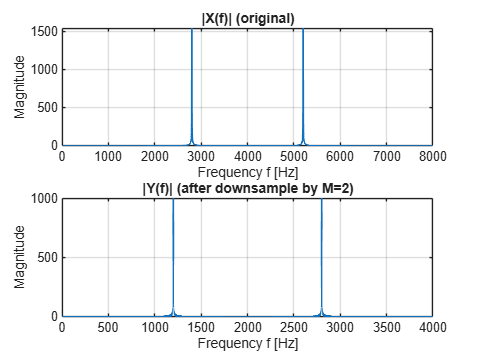

% Parameters:
fs = 8000;         % sampling rate (Hz)
Ts = 1/fs;
N  = 4096;         % FFT length
t  = (0:N-1) * Ts; 

% Use a tone to alias AFTER fs /2 -> (0.35 * fs -> 2800 Hz @ fs=8 kHz)
f0 = 0.35 * fs; % Hz
x  = cos(2*pi*f0*t); % discrete signal

% Downsample/decimate with M = 2
M    = 2;
y    = x(1:M:end);
fs_y = fs/M;       % new sampling rate (Hz)
Ty = 1/fs_y;

% Zero-pad y to length N to campare results
yZ = zeros(1, N);
yZ(1:length(y)) = y;

% Compute the FFT of the original and downsampled signals
X = fft(x, N);
Y = fft(yZ, N);
fx = (0:N-1) * (fs/N); % Frequency vector for original signal
fy = (0:N-1) * (fs_y/N); % Frequency vector for downsampled signal

figure('Color', 'w');
subplot(2, 1, 1); plot(fx, abs(X), 'LineWidth', 1.2); grid on;
title('|X(f)| (original)'); xlabel('Frequency f [Hz]'); ylabel('Magnitude');
subplot(2, 1, 2); plot(fy, abs(Y), 'LineWidth', 1.2); grid on;
title('|Y(f)| (after downsample by M=2)'); xlabel('Frequency f [Hz]'); ylabel('Magnitude');

Q1: 1400 Hz

Q2: It drops every other sample, so the frequency pulse appears more often in sample-space

Q3: For M=2, nyquist is halved when Fs -> Fs /2, so for frequencies < Fs/4 avoid aliasing for downsampling wioth M=2

## Upsampling